# Step 1: Clear workspace and import data

clear
clc

% Importing data
data1 = load('data1.txt');
data2 = load('data2.txt');
data3 = load('data3.txt');
data4 = load('data4.txt');

## Step 2: Extract shear rates and shear stresses

shear_rate1 = data1(:,1);
shear_stress1 = data1(:,2);
shear_rate2 = data2(:,1);
shear_stress2 = data2(:,2);
shear_rate3 = data3(:,1);
shear_stress3 = data3(:,2);
shear_rate4 = data4(:,1);
shear_stress4 = data4(:,2);

## Step 3: Plot raw data

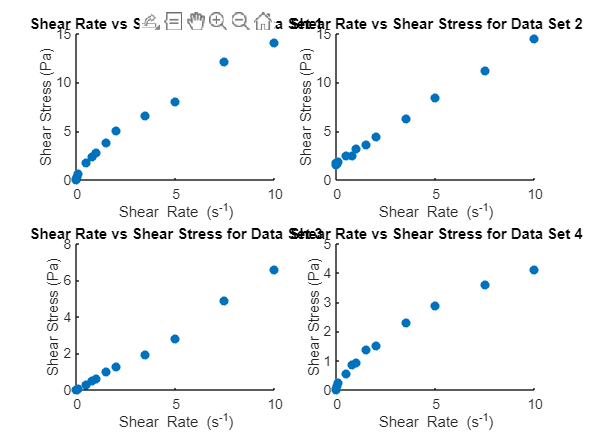

subplot(2,2,1);
scatter(shear_rate1, shear_stress1, 'filled');
title('Shear Rate vs Shear Stress for Data Set 1');
xlabel('Shear Rate (s^{-1})');
ylabel('Shear Stress (Pa)');

subplot(2,2,2);
scatter(shear_rate2, shear_stress2, 'filled');
title('Shear Rate vs Shear Stress for Data Set 2');
xlabel('Shear Rate (s^{-1})');
ylabel('Shear Stress (Pa)');

subplot(2,2,3);
scatter(shear_rate3, shear_stress3, 'filled');
title('Shear Rate vs Shear Stress for Data Set 3');
xlabel('Shear Rate (s^{-1})');
ylabel('Shear Stress (Pa)');

subplot(2,2,4);
scatter(shear_rate4, shear_stress4, 'filled');
title('Shear Rate vs Shear Stress for Data Set 4');
xlabel('Shear Rate (s^{-1})');
ylabel('Shear Stress (Pa)');

## Step 4: Curve fitting for different fluid behaviors

Newtonian fit

linear_fit1 = fitlm(shear_rate1, shear_stress1);
linear_fit2 = fitlm(shear_rate2, shear_stress2);
linear_fit3 = fitlm(shear_rate3, shear_stress3);
linear_fit4 = fitlm(shear_rate4, shear_stress4);

% Shear thinning (pseudoplastic) fit
[shear_thinning_fit1, gof1] = fit(shear_rate1, shear_stress1, 'power1');
[shear_thinning_fit2, gof2] = fit(shear_rate2, shear_stress2, 'power1');
[shear_thinning_fit3, gof3] = fit(shear_rate3, shear_stress3, 'power1');
[shear_thinning_fit4, gof4] = fit(shear_rate4, shear_stress4, 'power1');

% Shear thickening (dilatant) fit
[shear_thickening_fit1, gof5] = fit(shear_rate1, shear_stress1, 'power2');
[shear_thickening_fit2, gof6] = fit(shear_rate2, shear_stress2, 'power2');
[shear_thickening_fit3, gof7] = fit(shear_rate3, shear_stress3, 'power2');
[shear_thickening_fit4, gof8] = fit(shear_rate4, shear_stress4, 'power2');

% Bingham plastic fit
[bingham_fit1, gof9] = fit(shear_rate1, shear_stress1, 'poly1');
[bingham_fit2, gof10] = fit(shear_rate2, shear_stress2, 'poly1');
[bingham_fit3, gof11] = fit(shear_rate3, shear_stress3, 'poly1');
[bingham_fit4, gof12] = fit(shear_rate4, shear_stress4, 'poly1');

## Step 5: Plot fitted models over the data

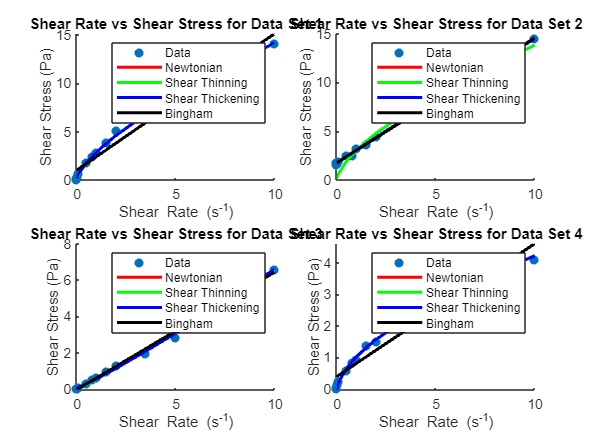

subplot(2,2,1);
scatter(shear_rate1, shear_stress1, 'filled');
hold on;
plot(shear_rate1, predict(linear_fit1, shear_rate1), 'r-', 'LineWidth', 2);
plot(shear_rate1, shear_thinning_fit1(shear_rate1), 'g-', 'LineWidth', 2);
plot(shear_rate1, shear_thickening_fit1(shear_rate1), 'b-', 'LineWidth', 2);
plot(shear_rate1, bingham_fit1(shear_rate1), 'k-', 'LineWidth', 2);
title('Shear Rate vs Shear Stress for Data Set 1');
xlabel('Shear Rate (s^{-1})');
ylabel('Shear Stress (Pa)');
legend('Data', 'Newtonian', 'Shear Thinning', 'Shear Thickening', 'Bingham');

subplot(2,2,2);
scatter(shear_rate2, shear_stress2, 'filled');
hold on;
plot(shear_rate2, predict(linear_fit2, shear_rate2), 'r-', 'LineWidth', 2);
plot(shear_rate2, shear_thinning_fit2(shear_rate2), 'g-', 'LineWidth', 2);
plot(shear_rate2, shear_thickening_fit2(shear_rate2), 'b-', 'LineWidth', 2);
plot(shear_rate2, bingham_fit2(shear_rate2), 'k-', 'LineWidth', 2);
title('Shear Rate vs Shear Stress for Data Set 2');
xlabel('Shear Rate (s^{-1})');
ylabel('Shear Stress (Pa)');
legend('Data', 'Newtonian', 'Shear Thinning', 'Shear Thickening', 'Bingham');

subplot(2,2,3);
scatter(shear_rate3, shear_stress3, 'filled');
hold on;
plot(shear_rate3, predict(linear_fit3, shear_rate3), 'r-', 'LineWidth', 2);
plot(shear_rate3, shear_thinning_fit3(shear_rate3), 'g-', 'LineWidth', 2);
plot(shear_rate3, shear_thickening_fit3(shear_rate3), 'b-', 'LineWidth', 2);
plot(shear_rate3, bingham_fit3(shear_rate3), 'k-', 'LineWidth', 2);
title('Shear Rate vs Shear Stress for Data Set 3');
xlabel('Shear Rate (s^{-1})');
ylabel('Shear Stress (Pa)');
legend('Data', 'Newtonian', 'Shear Thinning', 'Shear Thickening', 'Bingham');

subplot(2,2,4);
scatter(shear_rate4, shear_stress4, 'filled');
hold on;
plot(shear_rate4, predict(linear_fit4, shear_rate4), 'r-', 'LineWidth', 2);
plot(shear_rate4, shear_thinning_fit4(shear_rate4), 'g-', 'LineWidth', 2);
plot(shear_rate4, shear_thickening_fit4(shear_rate4), 'b-', 'LineWidth', 2);
plot(shear_rate4, bingham_fit4(shear_rate4), 'k-', 'LineWidth', 2);
title('Shear Rate vs Shear Stress for Data Set 4');
xlabel('Shear Rate (s^{-1})');
ylabel('Shear Stress (Pa)');
legend('Data', 'Newtonian', 'Shear Thinning', 'Shear Thickening', 'Bingham');

## Step 6: Calculate and plot viscosity curves

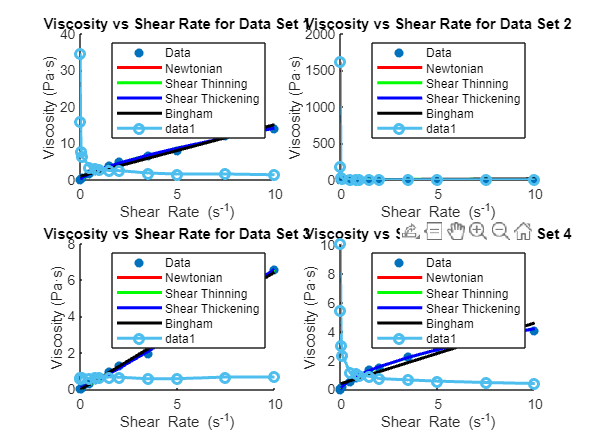

viscosity1 = shear_stress1 ./ shear_rate1;
viscosity2 = shear_stress2 ./ shear_rate2;
viscosity3 = shear_stress3 ./ shear_rate3;
viscosity4 = shear_stress4 ./ shear_rate4;

subplot(2,2,1);
plot(shear_rate1, viscosity1, 'o-', 'LineWidth', 2);
title('Viscosity vs Shear Rate for Data Set 1');
xlabel('Shear Rate (s^{-1})');
ylabel('Viscosity (Pa·s)');

subplot(2,2,2);
plot(shear_rate2, viscosity2, 'o-', 'LineWidth', 2);
title('Viscosity vs Shear Rate for Data Set 2');
xlabel('Shear Rate (s^{-1})');
ylabel('Viscosity (Pa·s)');

subplot(2,2,3);
plot(shear_rate3, viscosity3, 'o-', 'LineWidth', 2);
title('Viscosity vs Shear Rate for Data Set 3');
xlabel('Shear Rate (s^{-1})');
ylabel('Viscosity (Pa·s)');

subplot(2,2,4);
plot(shear_rate4, viscosity4, 'o-', 'LineWidth', 2);
title('Viscosity vs Shear Rate for Data Set 4');
xlabel('Shear Rate (s^{-1})');
ylabel('Viscosity (Pa·s)');

## Step 7: Interpolate shear stress at 1.5 s^-1

shear_stress_at_1_5_1 = interp1(shear_rate1, shear_stress1, 1.5);
shear_stress_at_1_5_2 = interp1(shear_rate2, shear_stress2, 1.5);
shear_stress_at_1_5_3 = interp1(shear_rate3, shear_stress3, 1.5);
shear_stress_at_1_5_4 = interp1(shear_rate4, shear_stress4, 1.5);

## Step 8: Report results

disp('Shear stress at 1.5 s^-1:')

Shear stress at 1.5 s^-1:


disp(['Data Set 1: ', num2str(shear_stress_at_1_5_1, '%.4f'), ' Pa'])

Data Set 1: 3.8656 Pa


disp(['Data Set 2: ', num2str(shear_stress_at_1_5_2, '%.4f'), ' Pa'])

Data Set 2: 3.6750 Pa


disp(['Data Set 3: ', num2str(shear_stress_at_1_5_3, '%.4f'), ' Pa'])

Data Set 3: 0.9810 Pa


disp(['Data Set 4: ', num2str(shear_stress_at_1_5_4, '%.4f'), ' Pa'])

Data Set 4: 1.3796 Pa



disp(' ')

disp('R^2 values for different models:')

R^2 values for different models:


disp(['Data Set 1: Newtonian R^2 = ', num2str(linear_fit1.Rsquared.Ordinary, '%.4f'), ...
    ', Shear Thinning R^2 = ', num2str(gof1.rsquare, '%.4f'), ...
    ', Shear Thickening R^2 = ', num2str(gof5.rsquare, '%.4f'), ...
    ', Bingham R^2 = ', num2str(gof9.rsquare, '%.4f')])

Data Set 1: Newtonian R^2 = 0.9740, Shear Thinning R^2 = 0.9957, Shear Thickening R^2 = 0.9958, Bingham R^2 = 0.9740


disp(['Data Set 2: Newtonian R^2 = ', num2str(linear_fit2.Rsquared.Ordinary, '%.4f'), ...
    ', Shear Thinning R^2 = ', num2str(gof2.rsquare, '%.4f'), ...
    ', Shear Thickening R^2 = ', num2str(gof6.rsquare, '%.4f'), ...
    ', Bingham R^2 = ', num2str(gof10.rsquare, '%.4f')])

Data Set 2: Newtonian R^2 = 0.9985, Shear Thinning R^2 = 0.9501, Shear Thickening R^2 = 0.9987, Bingham R^2 = 0.9985


disp(['Data Set 3: Newtonian R^2 = ', num2str(linear_fit3.Rsquared.Ordinary, '%.4f'), ...
    ', Shear Thinning R^2 = ', num2str(gof3.rsquare, '%.4f'), ...
    ', Shear Thickening R^2 = ', num2str(gof7.rsquare, '%.4f'), ...
    ', Bingham R^2 = ', num2str(gof11.rsquare, '%.4f')])

Data Set 3: Newtonian R^2 = 0.9949, Shear Thinning R^2 = 0.9968, Shear Thickening R^2 = 0.9971, Bingham R^2 = 0.9949


disp(['Data Set 4: Newtonian R^2 = ', num2str(linear_fit4.Rsquared.Ordinary, '%.4f'), ...
    ', Shear Thinning R^2 = ', num2str(gof4.rsquare, '%.4f'), ...
    ', Shear Thickening R^2 = ', num2str(gof8.rsquare, '%.4f'), ...
    ', Bingham R^2 = ', num2str(gof12.rsquare, '%.4f')])

Data Set 4: Newtonian R^2 = 0.9485, Shear Thinning R^2 = 0.9972, Shear Thickening R^2 = 0.9974, Bingham R^2 = 0.9485


## Step 9: Determine fluid with highest shear stress at 1.5 s^-1

shear_stresses_at_1_5 = [shear_stress_at_1_5_1, shear_stress_at_1_5_2, shear_stress_at_1_5_3, shear_stress_at_1_5_4];
[max_stress, max_index] = max(shear_stresses_at_1_5);
disp(' ')

disp(['The fluid with the highest shear stress at 1.5 s^-1 is Data Set ', num2str(max_index), ...
    ' with ', num2str(max_stress, '%.4f'), ' Pa'])

The fluid with the highest shear stress at 1.5 s^-1 is Data Set 1 with 3.8656 Pa


## Step 10: Analyze viscosity curves

disp(' ')

disp('Viscosity Curve Analysis:')

Viscosity Curve Analysis:


disp('Data Set 1: ') % Add your comment here based on the viscosity curve

Data Set 1: 


disp('Data Set 2: ') % Add your comment here based on the viscosity curve

Data Set 2: 


disp('Data Set 3: ') % Add your comment here based on the viscosity curve

Data Set 3: 


disp('Data Set 4: ') % Add your comment here based on the viscosity curve

Data Set 4: 
